# **Compare Solar Panel Energy Production to Theory:**

## **Theoretical Power Production:**

Define the latitude and the solar declination angle:

latitude = 42 + 17/60;
solarDeclination = 23.45;

Convert the variables to radians:

latitude = latitude * pi/180;
solarDeclination = deg2rad(solarDeclination);

Define the time interval

t = 5.5:0.25:20;
LST  = t - 1 + 14.6/60;

Determine the amount of solar irradiance on the solar panels: $S_{panel} = S_{inc}\sin(\alpha)$, where $S_{inc} = 1.4883 \times 0.7 ^ {\sin(\alpha) ^ {-0.678}}$ and $\alpha$ is the elevation of the sun, given by: $\sin(\beta)\sin(\delta) + \cos(\beta)\cos(\delta)\cos(15 \times (LST - 12))$

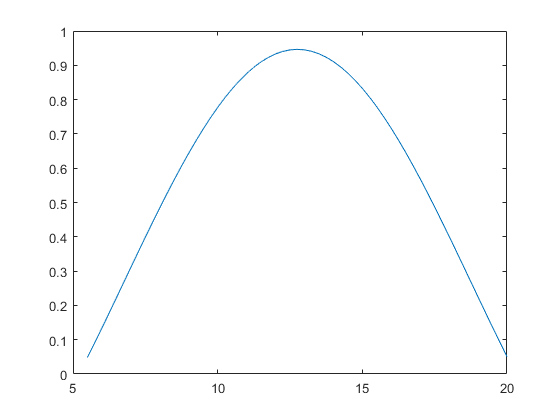

sunAngle = sin(solarDeclination) * sin(latitude) + cos(solarDeclination) * cos(latitude) * cosd(15 * (LST - 12));
plot(t, sunAngle);

Calculate the final theoretical production for the entire solar panel array:

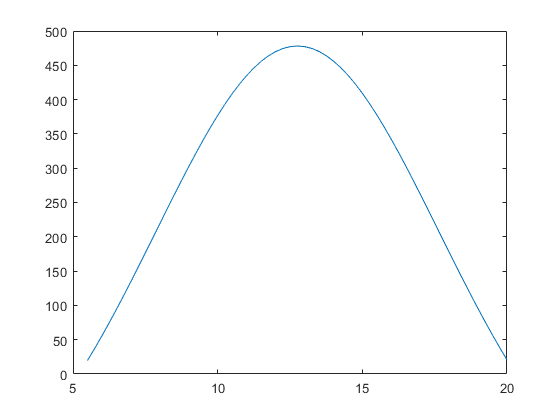

S_incident = 1.4883 * 0.7 .^ sunAngle .^ -0.678;
productionTheory = 270 * S_incident .* sunAngle;
plot(t, productionTheory);

plot(SolarArrayProduction.Timestamp, SolarArrayProduction.AH3);

Error using plot
Not enough input arguments.